% Initiating variables
targetPos = 0;
posCur = 0;
velCur = 0;
accel = 0;

% Sets the max iterations you want to run through
maxTime = 500;

pos = zeros(1,maxTime);
targetPosSaver = zeros(1,maxTime);
error = zeros(1,maxTime);
timesteps = 1:maxTime;
integ = 0;
posPrev = 0;

% These are the coefficients that you adjust to tweak the PID
Kp = 0.2926;
Ki = 0.1650;
Kd = 0.8955;

% This changes the amount of time you loop per second
dt = 1;

for time = 1:dt:maxTime

    % This is the equation that determines my target height
    targetPos = 5*sind(time*5) + 50 + 2*sind(8*time);
    targetPosSaver(1,time) = targetPos;

    % These variables calculate and store the previous and current error
    errorCur = targetPos-posCur;
    errorPre = targetPos-posPrev;

    % These variables calulate the integral, derivitave, and then the acceleration
    integ = integ + errorCur;
    deriv = (errorCur-errorPre)/dt;
    accel = errorCur*Kp + integ*Ki + deriv*Kd;

    % This variable saves teh current position so that it can be used in
    % the next iteration to calculate the previous error
    posPrev = posCur;

    % This sends the accelration, current position, and current velocity to
    % a function which finds out new current velocity and position
    [posCur,velCur] = phySim(accel,posCur,velCur);

    % This checks if we hit the ground and stops our movement if so
    if posCur <=0
        posCur = 0;
        velCur = 0;
    end

    % This saves our all our positions over time so that we can later graph it
    pos(1,time) = posCur;

    % This saves all of our errors over time so that we can later use
    % them to determine how good our PID
    % coefficients were
    error(1,time) = errorCur;
    

end

absError = abs(error);
avgError = mean(absError)

avgError = 0.5751

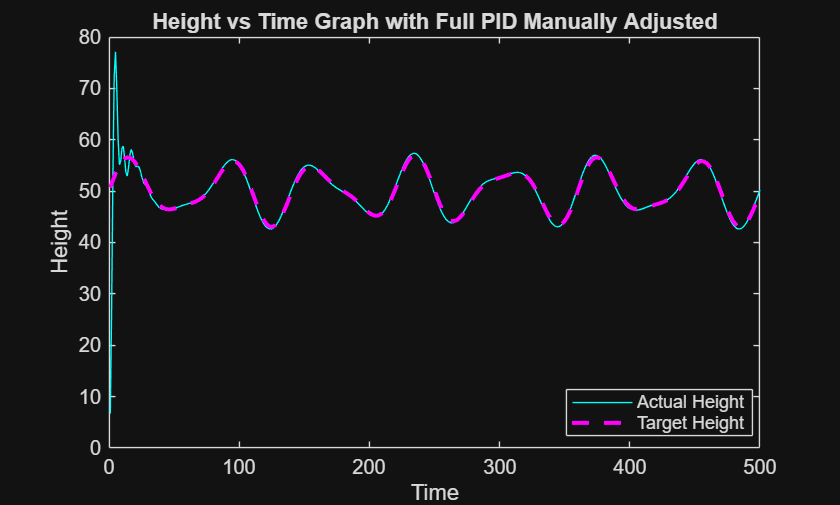



% This plots both the target height and actual height
plot(timesteps,pos,'cyan-')
hold on
plot(timesteps,targetPosSaver,"magenta--",LineWidth=2)
title("Height vs Time Graph with Full PID Manually Adjusted")
xlabel("Time")
ylabel("Height")
legend("Actual Height","Target Height")
legend(["Actual Height", "Target Height"], "Position", [0.6744 0.1362 0.2220, 0.0924])
hold off